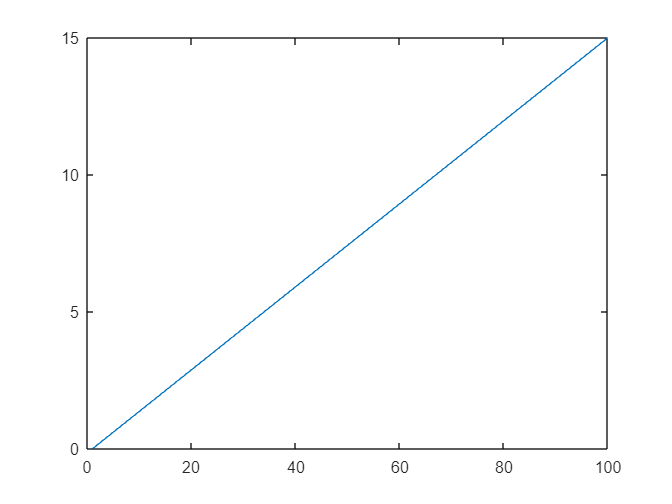

%% HW2
load ratrecord.mat
plot(t);

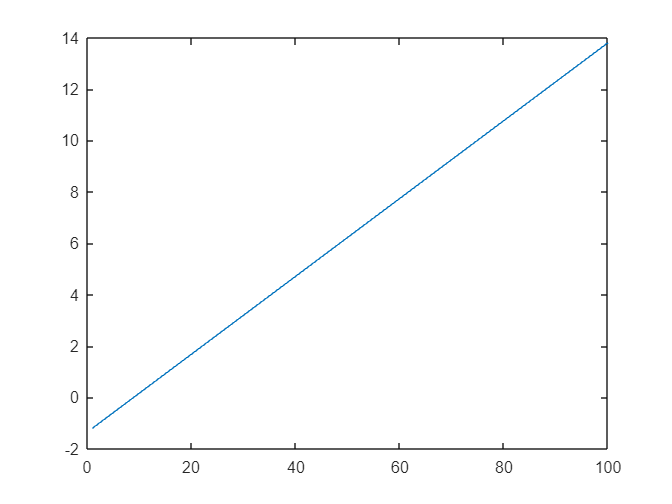

target=1.2;
plot(t-target);

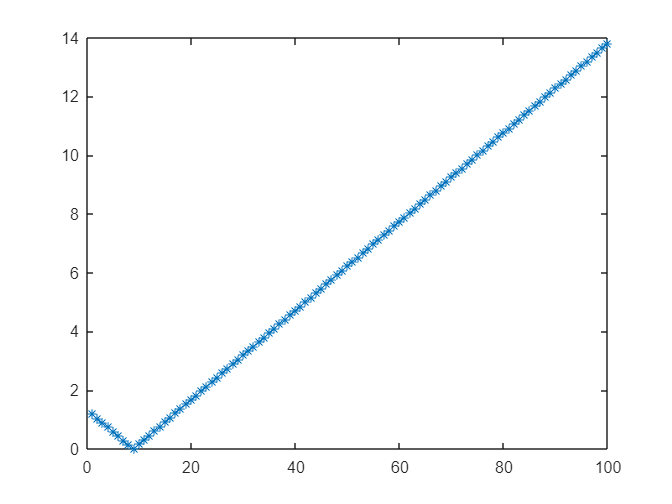

plot(abs(t-target),'*')

min(abs(t-target))

ans = 0.0121

help min

 min    Minimum elements of an array.
    M = min(X) is the smallest element in the vector X. If X is a matrix,
    M is a row vector containing the minimum element from each column. For 
    N-D arrays, min(X) operates along the first non-singleton dimension.
 
    When X is complex, the minimum is computed using the magnitude
    min(ABS(X)). In the case of equal magnitude elements the phase angle 
    min(ANGLE(X)) is used.
 
    [M,I] = min(X) also returns the indices corresponding to the minimum
    values. The values in I index into the dimension of X that is being
    operated on. If X contains more than one element with the minimum
    value, then the index of the first one is returned.
 
    C = min(X,Y) returns an array with the smallest elements taken from X 
    or Y. X and Y must have compatible sizes. In the simplest cases, they 
    can be the same size 

%1
n = 1/21;
mantissa = 7;
binary_rep = zeros(1, mantissa);

for i = 1:mantissa
    n = n * 2;
    if n >= 1
        binary_rep(i) = 1;
        n = n - 1;
    else
        binary_rep(i) = 0;
    end
end

disp(['1/21 with 7-bit mantissa: ', num2str(binary_rep)]);

1/21 with 7-bit mantissa: 0  0  0  0  1  1  0


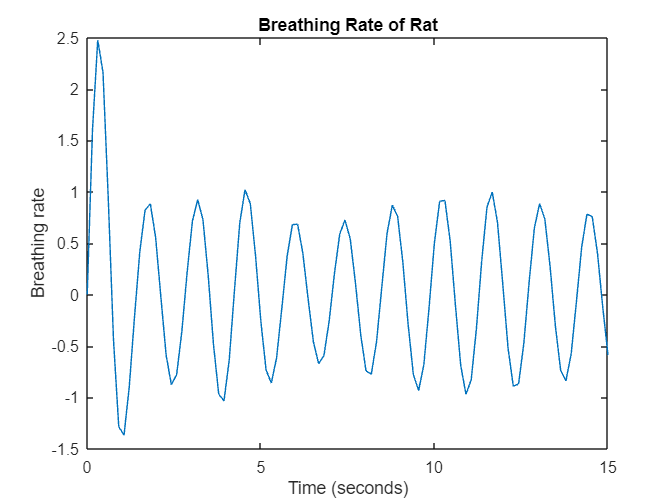

%2
load('C:\Users\adi03\Downloads\ratrecord.mat');

time = linspace(0, 15, length(data));

figure;
plot(time, data);
xlabel('Time (seconds)');
ylabel('Breathing rate');
title('Breathing Rate of Rat');


% Choose one interval [a b] where the recording goes through 0
a = 1; 
b = 10; % passes through 0 at 9

f = @(t) sign(interp1(time, data, t));
threshold = 1e-6;
max_iterations = 1000; % Maximum number of iterations

% Bisection Method
iteration_bisection = 0;
tic;
while (b - a) / 2 > threshold && iteration_bisection < max_iterations
    
    c = (a + b) / 2;
    if f(c) == 0
        break;
    elseif f(c) * f(a) < 0 % right squeeze
        b = c;
    else                    %left squeeze f(c) * f(b) <0
        a = c;
    end
    iteration_bisection = iteration_bisection + 1;
end
time_zero_bisection = c;

fprintf('Time at zero using Bisection Method: %f\n', time_zero_bisection);

Time at zero using Bisection Method: 7.053607


fprintf('Number of iterations for Bisection Method: %d\n', iteration_bisection);

Number of iterations for Bisection Method: 23


fprintf('Execution time for Bisection Method: %f seconds\n', toc);

Execution time for Bisection Method: 3401.923812 seconds



% False Position Method
a = 1; 
b = 10; % passes through 0 at 9
iteration_false_position = 0;
tic;
while abs(b - a) > threshold && iteration_false_position < max_iterations
    
    c = b - f(b) * (b - a) / (f(b) - f(a));
    if f(c) == 0
        break;
    elseif f(c) * f(b) < 0
        a = b;
        b = c;
    else
        b = c;
    end
    iteration_false_position = iteration_false_position + 1;
end
time_zero_false_position = c;

fprintf('Time at zero using False Position Method: %f\n', time_zero_false_position);

Time at zero using False Position Method: 7.053608


fprintf('Number of iterations for False Position Method: %d\n', iteration_false_position);

Number of iterations for False Position Method: 24


fprintf('Execution time for False Position Method: %f seconds\n', toc);

Execution time for False Position Method: 3401.939164 seconds



% BONUS: Secant Method
a = 1; 
b = 10; % passes through 0 at 9
pk_0 = a;
pk_1 = b;
f0 = f(a)

f0 = 1

f1 = f(b)

f1 = -1


iteration_secant = 0;
tic;
while abs(f1) > threshold && iteration_secant < max_iterations
    x2 = pk_1 - (f1 * (pk_1 - pk_0)) / (f1 - f0);
    f2 = f(x2);
    
    % Update values for next iteration
    pk_0 = pk_1;
    f0 = f1;
    pk_1 = x2;
    f1 = f2;
    
    iteration_secant = iteration_secant + 1;
end

disp(['Result obtained by Secant Method: ', num2str(x2), ' seconds']);

Result obtained by Secant Method: -Inf seconds


disp(['Number of iterations for Secant Method: ', num2str(iteration_secant)]);

Number of iterations for Secant Method: 7


disp(['Execution time for Secant Method: ', num2str(toc), ' seconds']);

Execution time for Secant Method: 3401.9513 seconds
